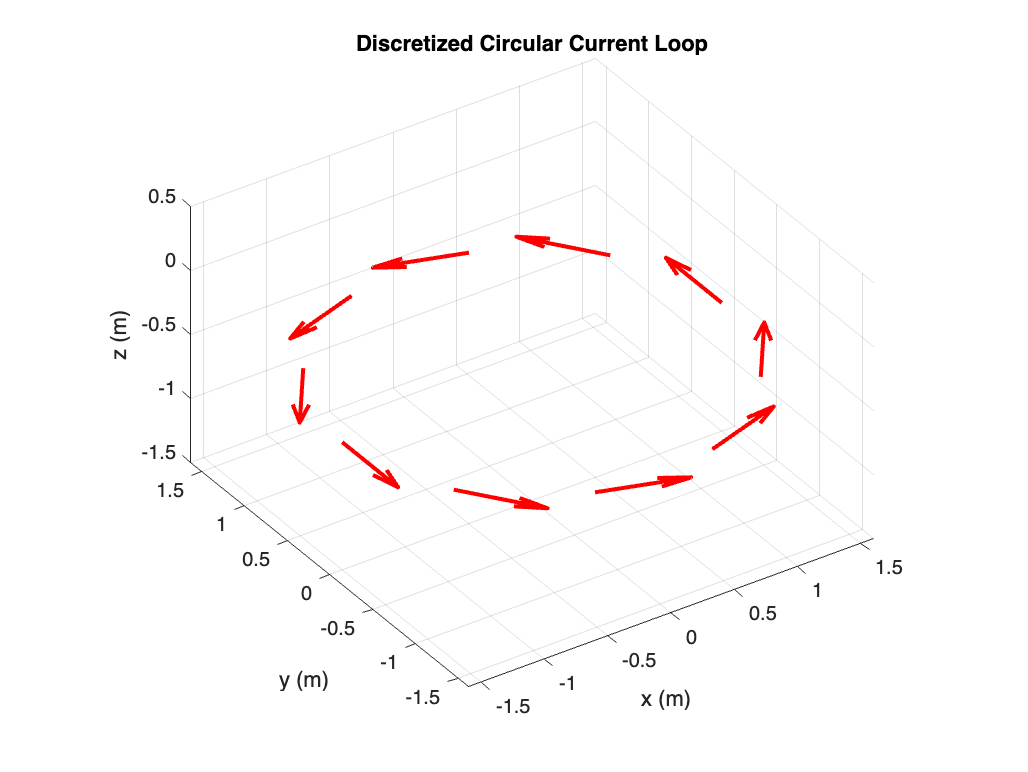

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Session 1 | Step 1
%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Rodrigo Gamboa & Francisco Montes | May 2024


%-OBJECTIVE-%

%Create and visualize a discretized loop made of N arrows,
%simbolizing electric current differentials, so that the whole
%configuration will approximate a circular wire (coil), with an
%associated constant electric current I. The more currents the better.

%Recall commenting and completing all necessary code from now on,
%as this will impact the quality and grade of the associate Deliverable.


%-----------------------------------------------------------------------
%Code starts here
%Complete the code in the left, using the comments in the right.
%-----------------------------------------------------------------------


clear all;          %Clear all variables from the workspace
clc;                %Clear command window
close all;          %Clear all elements on figures

nl = 1;             %Declare a variable "nl" that will
                    %represent the number of wire loops in your
                    %simulation. One for a configuration called
                    % a _circular loop_? %Two or more for a configuration
                    % referred to as a _solenoid_?


ds = 0.1;           % Declare a variable "ds", for lenght differential.
                    % Set it equal to 0.1 as a starting point.


x = -5:ds:5;
y = -5:ds:5;
z = x;              %Define x, y and z vectors, all equal,
                    %ranging from -5 to 5, in steps of ds.
                    %This will define our 3D working space.

                    %When correctly done, each vector will
                    %appear in the Workspace as a 1x101
                    %double array.


Lx = length(x);
Ly = length(y);
Lz = length(z);     %Using the length(A) function,
                    %where A can be a vector or array,
                    %declare Lx, Ly and Lz
                    %variables, setting them
                    %equal to the number of elements
                    %in the x, y and z vectors (i.e. the
                    %vector lenghts).


rw = 0.2;           %Using a variable labelled rw, declare the
                    %wire thickness, use a value of 0.2.

I = 300;            %Using a variable I, declare the
                    %associate electric current
                    %(use value of 300 Amperes).


%Uncomment the following code.

mo=4*pi*1e-7;       %What is this? Permeability of free space. (What are the units _Henry per meter (H/m)_?)
km=mo*I/(4*pi);     %And this? A constant related to the magnetic field strength due to a current element. (What are the units _Tesla meter (T·m) or Weber per meter (Wb/m)_)


N = 10;             %Declare a variable N, that will define the # of points per loop.
R = 1.5;            %Declare a variable R, as the radious if the wire, use 1.5 as default.
sz = 1;             %Declare a variable sz, setting it equal to 1. This will represent the
                    %loop step size in the z axis direction.


s = 1;              %Declare an s variable (equal to 1), representing the loop "number".

dtheta = 2*pi/N;    %Define the "differential angle step" (dtheta) with respect to the center
                    %of the circular wire (coil), consider that it has to cover an
                    %angular displacement of 2*pi. Think about it!

dl = R * dtheta;    %Define the "dl" length differential, coupled with the associated dtheta.
                    %Consider that dtheta is in radians.


ang = 0:dtheta:2*pi-dtheta; %Define a vector called "ang" (for angle),
                            %ranging from 0 to 2*pi-dtheta, in steps of dtheta.
                            %This will store angle values to complete a cycle
                            % with steps dtheta, around the coil. Why from
                            % 0 to 2*pi-dtheta: _To avoid repeating the last point (2*pi is the same as 0) and ensure 'N' distinct points._


%Start here a for loop, looping a dummie variable
%going from 1 to nl (the number of loops in the system).

for i = 1:nl
%<inside for loop>
%Uncomment the following lines, explore and describe what each of them is
%doing

    Px(s:s+N-1)=R*cos(ang);         % Calculates the x-coordinates of the N points forming the circular loop with radius R.
    Py(s:s+N-1)=R*sin(ang);         % Calculates the y-coordinates of the N points forming the circular loop with radius R.
    Pz(s:s+N-1)=-nl/2*sz+(i-1)*sz;  % Calculates the z-coordinates for each point. This allows for multiple loops to be stacked along the z-axis, centered around z=0.

    dx(s:s+N-1)=-Py(s:s+N-1)*dtheta; % Calculates the x-component of the differential current element (dl) tangential to the circle. It's -R*sin(theta)*dtheta.
    dy(s:s+N-1)=Px(s:s+N-1)*dtheta;  % Calculates the y-component of the differential current element (dl) tangential to the circle. It's R*cos(theta)*dtheta.

    s=s+N;                          % Updates the starting index 's' for the next loop's points if nl > 1.

%<inside for loop>
end %End for loop here.

dz(1:N*nl)=0;                       % Sets the z-component of the differential current element (dl) to zero, as the current flows in the x-y plane.


figure(1) %Call figure 1


%Use quiver3 function, to visualize the wire of currents.
%Recall that quiver3(X,Y,Z,U,V,W) plots arrows with directional components
%U, V, and W at the Cartesian coordinates specified by X, Y, and Z.

quiver3(Px,Py,Pz,dx,dy,dz,0.5,'-r','LineWidth',2) % '0.5' is the scaling factor for the arrows, '-r' sets the line style to solid and color to red, 'LineWidth',2 sets the width of the arrow lines to 2 points.

%Uncomment for setting a proper viewing perspective.
view(-34,33)
axis equal % Ensures that the scaling factors are the same for all axes, so circles appear as circles.
xlabel('x (m)')
ylabel('y (m)')
zlabel('z (m)')
title('Discretized Circular Current Loop')
grid on


%%%%%%%%%%%%%%%%%%%%%%%%%%%
%   Session 1 | Step 2    %
%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Rodrigo Gamboa & Francisco Montes | May 2024.


%After "Uncomment for setting a proper viewing perspective"
%view(-34,33) from previous step.


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Magnetic-field Calculation & Visualization %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%Using the results obtained from the Biot-Savart law, get the B-field
%at each point in space, around the current loop.


dBx = zeros(Lx,Ly,Lz);
dBy = zeros(Lx,Ly,Lz);
dBz = zeros(Lx,Ly,Lz); %Create three, 3x3 equal arrays, dBx,
                                        %dBy & dBz, each spanning from 1
                                        %to Lx, 1 to Ly and 1 to Lz, and
                                        %initialize all values to zero. You should
                                        %obtain in the workspace, three 101x101x101
                                        % objects (dBx, dBy, dBz).

                                        %What do you think we are to use
                                        %this for: _To store the x, y, and z components of the magnetic field at every point in our 3D working space, which will be calculated by summing the contributions from each differential current element using the Biot-Savart Law._


for I_idx = 1:Lx                        %Open a for loop using "I_idx" as index, going from 1 to Lx.
    for J_idx = 1:Ly                    %Same but for Ly, use a "J_idx" index.
        for K_idx = 1:Lz                %Same but for Lz, use a "K_idx" index.

            for L_idx = 1:nl*N          %Open a 4th for loop, usin an "L_idx" index, running from 1 to nl*N (Why? _Because nl*N represents the total number of current differential elements (dl) across all loops in our simulation. We need to sum the magnetic field contribution from each dl at every point in space._).

            %<inside the 4th loop>

                                         % Make a drawing (diagram), using a position vector
                                         % from the center of the coil to each current element, given by
                                         % r´= Px(L)i+Py(L)j+Pz(L)k, and a position vector
                                         % from the center of the coil to the place in space
                                         % where we want to compute the B-fiel given by
                                         % R´= x(I)i+y(J)j+z(K)k. With this, find the position vector
                                         % from each current element to the place in space
                                         % where we want to compute the B-fiel, given by
                                         % r = (rx)i+(ry)j+(rz)k


                rx = x(I_idx) - Px(L_idx); %Write here the rx component
                ry = y(J_idx) - Py(L_idx); %Same but for the ry component
                rz = z(K_idx) - Pz(L_idx); %Same but for the rz component

                r = sqrt(rx^2 + ry^2 + rz^2 + rw^2); %Get the magnitude

                r3 = r^3;                   %Declate an r3 variable
                                            %equal to the third power of r


                % Using Biot-Savart´s original expression, use a generic
                % dl = (dx)i+(dy)j and r = (rx)i+(ry)j+(rz)k to compute the
                % cross product between dl and r, to find three independent
                % expression for the components of the B-fiel we want to
                % compute, dBx(I,J,K), dBy(I,J,K) and dBz(I,J,K). Do not forget
                % to update or rewrite the former components, between each
                % cycle.

                % Biot-Savart Law: dB = (mu_0 * I / 4*pi) * (dl x r) / r^3
                % dl = (dx(L)i + dy(L)j + dz(L)k) where dz(L) is 0 for our circular loop
                % r = (rx i + ry j + rz k)

                % dl x r components:
                % (dy(L)*rz - dz(L)*ry) i = (dy(L)*rz - 0*ry) i = dy(L)*rz i
                % (dz(L)*rx - dx(L)*rz) j = (0*rx - dx(L)*rz) j = -dx(L)*rz j
                % (dx(L)*ry - dy(L)*rx) k

                dBx(I_idx,J_idx,K_idx) = dBx(I_idx,J_idx,K_idx) + km * (dy(L_idx)*rz - dz(L_idx)*ry) / r3; %Write here the dBx(I,J,K) component
                dBy(I_idx,J_idx,K_idx) = dBy(I_idx,J_idx,K_idx) + km * (dz(L_idx)*rx - dx(L_idx)*rz) / r3; %Same but for the dBy(I,J,K) component
                dBz(I_idx,J_idx,K_idx) = dBz(I_idx,J_idx,K_idx) + km * (dx(L_idx)*ry - dy(L_idx)*rx) / r3; %Same but for the dBz(I,J,K) component

            %<inside the 4th loop>

            end %Close the 4th loop

        end %Close the 3rd loop
    end %Close the 2nd loop
end %Close the 1st loop


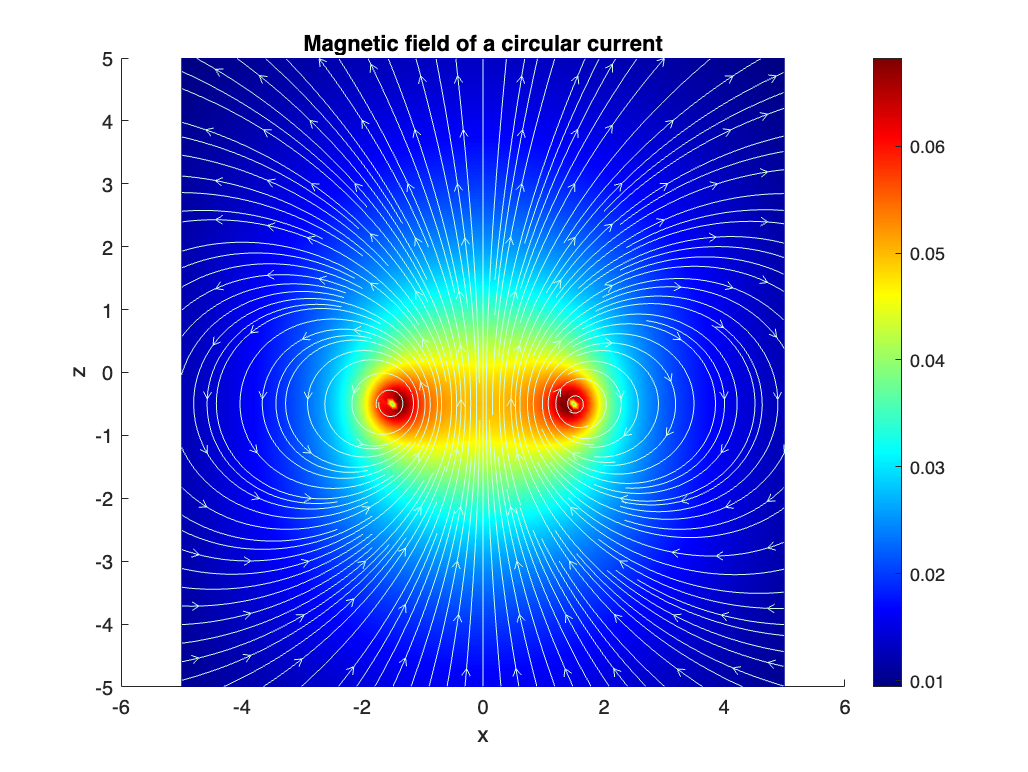


%------------------------------------------------------------
%Uncomment all the following, and explain (comment) each line
%------------------------------------------------------------

Bmag=sqrt(dBx.^2+dBy.^2+dBz.^2);    %?

centery=round(Ly/2);                %?
Bx_xz=squeeze(dBx(:,centery,:));    %?
Bz_xz=squeeze(dBz(:,centery,:));    %?
Bxz=squeeze(Bmag(:,centery,:));     %?

figure(2)                           %?
hold on

pcolor(x,z,(Bxz').^(1/3)); shading interp; colormap jet; colorbar    %?
h1=streamslice(x,z,Bx_xz',Bz_xz',3);                                 %?
set(h1,'Color', [0.8 1 0.9]);                                        %?
xlabel 'x'                                                           %? 
ylabel 'z'                                                           %?
title 'Magnetic field of a circular current'                         %?
zz(length(ang))=0;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%           Session 3 | Step 1              %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Rodrigo Gamboa & Francisco Montes | May 2024


%-OBJECTIVE-%

%In this activity you will learn to calculate the force between two sources of magnetic field.
%Specifically, you will calculate the force that a falling magnet (magnetic dipole) will experiment, 
%due to its interaction your former circular coil in the ground (with current I). 
%You will use and extend your code from the previous session.

%Recall commenting and completing all necessary code from now on,
%as this will impact the quality and grade of the associate Deliverable.


%-----------------------------------------------------------------------
%Code starts here (paste this work below your previous code viceversa)
%Complete the code in the left, using the comments in the right.
%-----------------------------------------------------------------------

%-----------------------------------------------------------------------%%
%-----------------------------------------------------------------------%%
%-------------------------Dipole Falling Part---------------------------%%
%-----------------------------------------------------------------------%%
%-----------------------------------------------------------------------%%

%Reseach and explain (in your own words), what is magnetic moment in general, 
%and for a permanent magnet (simple equations are allowed and expected):
%__________________________________________________________________________
%__________________________________________________________________________
%__________________________________________________________________________
%__________________________________________________________________________
%__________________________________________________________________________
%__________________________________________________________________________


%New code starts here!


mag = 1000;     %Declare a variable called "mag" (Magnetic moment of the magnet),
                %and initialize to 2000. What are its units %_____________?

m_mass = 0.004; %Declare the Magnet´s mass in kg, use 0.004 to begin.
                %How many grams is this_____________?

g = -9.81;
w = m_mass*g;   %Calculate Magnet´s weigth in N, and store it in a var. called "w". Don´t 
                %forget the sign.


zo = 5;         %Declare Magnet's initial position using a var. called "zo" (initialize it to 5).

dt = 0.05;      %Declare a time step "dt" equal to 0.05.

zm = []; zm(1) = zo; %Declate a vector called "zm" (magnet position) and store in its first 
                     %value the Magnet's initial position var.(the one you just defined above)

zmfree = []; zmfree(1) = zo; %Same as before, but using now a new vector called "zmfree", which stands
                             %for magnet´s position for the free fall case. Why do you
                             %think we introduced this _______________________________________________?


tt = []; tt(1) = 0;    %Declare a vector called "tt" (time), and initialize it to zero.

vz = []; vz(1) = 0;    %Declare a vector called "vz" (Z component for velocity), and initialize it to zero.

vzfree = []; vzfree(1) = 0; %Same as above but using now a vector labeled as "vzfree". Again, why _____________?

cc = 1;               %Introduce a var., called "cc" (an index counter), and set it equal to one.



path = animatedline;        %Use the animatedline function (use Matlab´s upper-right search function bar) to create an 

                            %animated line that has no data and adds it to the current axes. Later (a few lines below), 
                            %add points to the line in a loop using the addpoints function, add data.

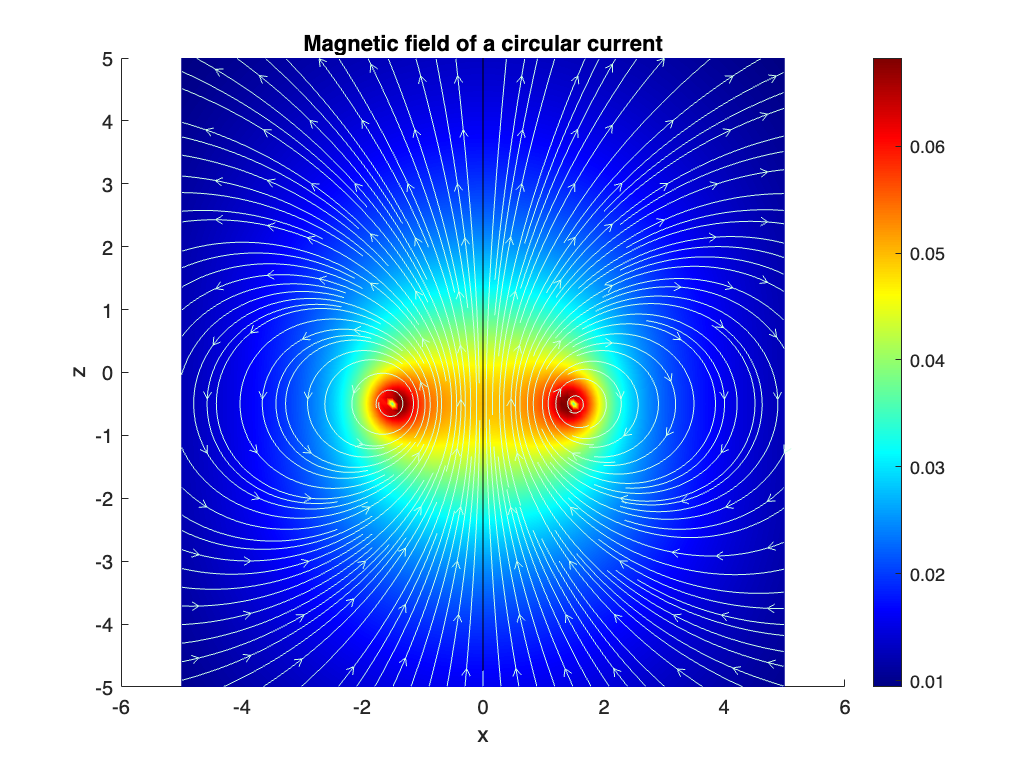

while (zm(cc) > -5) %Start a while loop running until the position of the magnet (dinamically) in z 
                    %is bigger than -5 (i.e. the bottom of the canvas). 
    
     %fprintf("Z position: %.2f\n", zm(cc))  %For diagnostics purposes, print the position of the magnet in z. 

     addpoints(path, 0, zm(cc))     %Using the addpoints function mentioned above, add points (the zm(cc) ones) 
                                    %to the path, centered in x=0.

     drawnow;       %Use drawnow to update and/or modify graphics objects and 
                    %want to see the updates on your canvas immediately.

     head = scatter(0, zm(cc), 100, 'filled');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%           Session 3 | Step 2              %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Rodrigo Gamboa & Francisco Montes | May 2024


%-----------------------------------------------------------------------
%Code continues from inside the while loop you used in the previous step
%-----------------------------------------------------------------------

 %<start  while>    %Start a while loop running until the position of the magnet (dinamically) in z 
                    %is bigger than -5 (i.e. the bottom of the canvas). 

                    %For diagnostics purposes, print the position of the magnet in z. 

      %Using the addpoints function mentioned above, add points (the zm(cc) ones) 
      %to the path, centered in x=0.

      %Use drawnow to update and/or modify graphics objects and 
      %want to see the updates on your canvas immediately.
    
    %head=scatter(0,zm(cc), 100,'filled'); %Uncomment this line and explain what its doing. 
   
    %%%%%%%%%%%%%%%%%
    %<NEW STUFF HERE>
    %%%%%%%%%%%%%%%%%

    %Go to the Canvas tab called "Stage 2: Magnetic Force between two magnetic
    %dipoles", read through it and perform the referred calculations. Using
    %this result. Get the force experienced by the Magnet Fm(cc), as a function
    %of z, i.e., as a function of it´s height. Use (adapt) your results to the 
    %variable names in yout code.


    Fm(cc) = (3 * zm(cc) * mag * mo * I * R^2) / (2 * (zm(cc)^2 + R^2)^(5/2));                                        %Magnetic force Fm(cc)

    F(cc) = Fm(cc) + w;                  %Net (total) force over the
                                             %magnet F(cc). Important, it 
                                             %is net force.
                                                                 
                                                                    

    a = F(cc) / m_mass;      %Using the total force get the instantaneous acceleration and label it as "a".
    pause(0.01);        %Use the pause function, with a value of 0.01, to grasp the
                        %head´s magnet movement.


    zm(cc+1) = zm(cc) + vz(cc)*dt + (1/2)*a*dt^2;    %Get new magnet´s position z(cc+1) using high school physics, 
                      %i.e. using constant ________________ kinematic equations. 

    zmfree(cc+1) = zmfree(cc) + vzfree(cc)*dt - (1/2)*9.81*dt^2;    %Do the same but for the free fall case,
                      %i.e., with no magnetic braking.

    vz(cc+1) = (zm(cc+1)-zm(cc))/dt;    %Get new magnet´s approx. velocity using basic velocity definition over
                      %a time interval dt, i.e., vz(cc+1) = delta(z)/delta(t).
      

    vzfree(cc+1) = (zmfree(cc+1)-zmfree(cc))/dt;               %Do the same (excepting the "just for fun steo") but for the free fall case,
                    %i.e., with no magnetic braking.
   
    cc = cc + 1;    %Increase the cc counter in one unit.
    
    delete(head)    %Uncomment 

%%<end while> Close the while loop
end

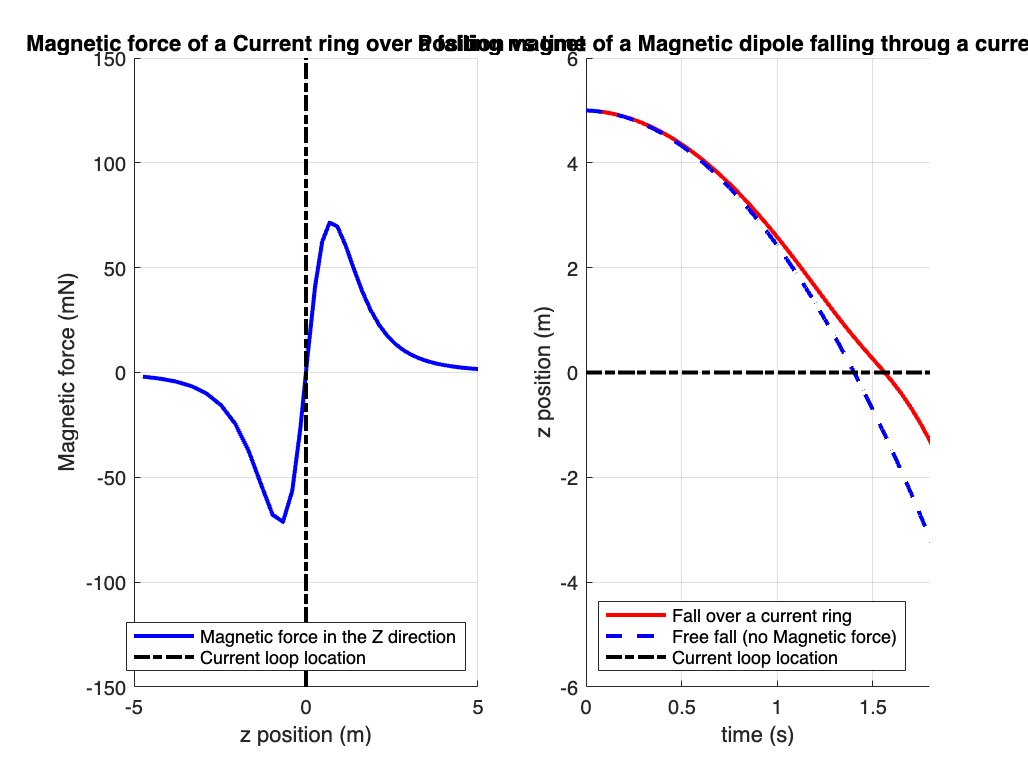


%Uncomment all of the following, and explain in 
%detail (in next step of the code, not now) what it does or will do. 

figure(4)
subplot(1,2,1)

hold on
plot(zm(1:length(Fm)),1000*Fm, '-b', 'LineWidth', 2) %Why do we have 1000Fm?
plot([0,0],[-150,150],'-.k','LineWidth', 2)
grid on
xlabel 'z position (m)'
ylabel 'Magnetic force (mN)'
title 'Magnetic force of a Current ring over a falling magnet'
legend('Magnetic force in the Z direction','Current loop location','Location','southeast')

subplot(1,2,2)

hold on
tt=0:dt:(cc-1)*dt;
plot(tt,zm,'-r', 'LineWidth', 2)
plot(tt,zmfree,'--b', 'LineWidth', 2)   
plot([0,1.8],[0,0],'-.k','LineWidth', 2)
grid on
xlabel 'time (s)'
ylabel 'z position (m)'
title 'Position vs time of a Magnetic dipole falling throug a current ring'
legend('Fall over a current ring','Free fall (no Magnetic force)', 'Current loop location','Location','southwest')
axis([0 1.8 -6 6])



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%FINALLY: Run and test your code for limit cases!
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%<THIS IS PART OF YOUR DELIVERABLE NO.1>


%(1) If the magnetic moment is zero, the magnet does not interact with the magnetic field.
%    It experiences no torque or force due to magnetism, so its motion is unaffected
%    by the magnetic field — behaves like a non-magnetic object.

%(2) Setting the magnet mass to 1 kg increases its inertia. 
%    It becomes less responsive to torques from magnetic forces, leading to slower angular
%    acceleration and reduced rotational dynamics in the field.

%(3) Increasing the magnetic moment by one order of magnitude makes the magnet
%    experience 10× stronger torque in the same magnetic field. 
%    This results in faster reorientation toward the magnetic field direction.

%(4) Decreasing the mass by one order of magnitude (e.g., from 1 kg to 0.1 kg)
%    reduces inertia, so the magnet becomes more responsive to applied torques.
%    It rotates more quickly under the same magnetic influence.

%(5) Typically, you get 3 plots:
%    (a) Orientation or angular position vs. time – shows how the magnet aligns over time.
%    (b) Angular velocity vs. time – indicates how fast the magnet is rotating.
%    (c) Magnetic torque vs. time – shows the torque applied due to the magnetic field.
%    These together illustrate the dynamic response of the magnetic dipole under
%    different mass and magnetic moment conditions.




